%% initialize environments
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "vaiueo2d.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path);
audio_file_manipulator.load_properties();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : vaiueo2d.wav
output_file_path : default.wav
signal shape : (17500, 1)
sample_rate: 22050 [Hz]
             Filename: 'D:\名城大学\研究室\演習\MatlabPractice\SourceCode\Analysis\STRAIGHT\STRAIGHTV40_007b\vaiueo2d.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 22050
         TotalSamples: 17500
             Duration: 0.7937
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16

--------------------------------------------



%% set LPC class parameters
start_point = 3748;  % あのスタート位置
continue_time = 32; % [ms]
continue_point = int32(continue_time * audio_file_manipulator.information.SampleRate / 1000);

%% generate LPC instance and confirm properties
lpc = LinearPredictiveCoding(audio_file_manipulator.signal(start_point : start_point + continue_point), audio_file_manipulator.information.SampleRate);
lpc.display_properties();

----------------------------------------------
---------- Linear Predictive Coding ----------
signal size : (707, 1)
window_mode : hamming
fft_point : 2048 [point]
sample_rate : 22050 [Hz]
linear_predictor_coefficient size : (1, 31)
order : 30
voicing_threshold : 0.000100
Ai size: (1, 31)
squared_sigma : 0.000012
spectrum_density size : (1025, 1)
residual_error size : (707, 1)
modified_autocorrelation size : (707, 1)
basic_frequency : 22050.000000 [Hz]
basic_period : 0.000045 [s]
----------------------------------------------



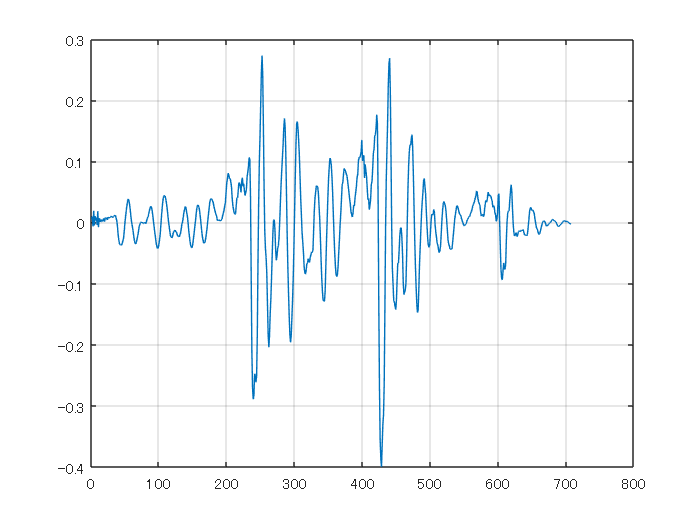

plot(lpc.residual_error);
grid on;